dir = readtable("PtDirectorySimple.xlsx");
i = 1; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.maxBetaChan{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
x = categorical({'A', 'B'}); 
anova1([allChan.Values(1:82), allChan.Values(82:82*2+1)], x)

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));
dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 2; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 1 R All Channels


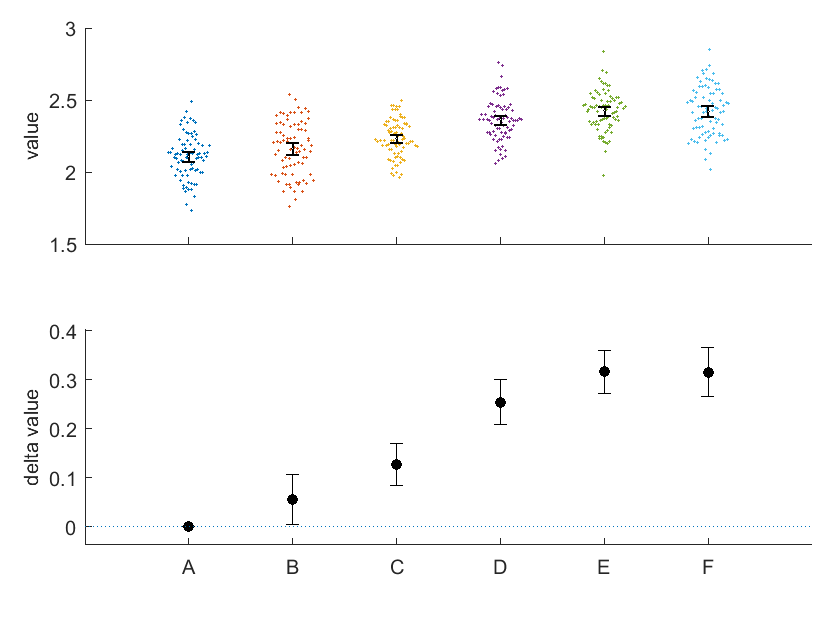

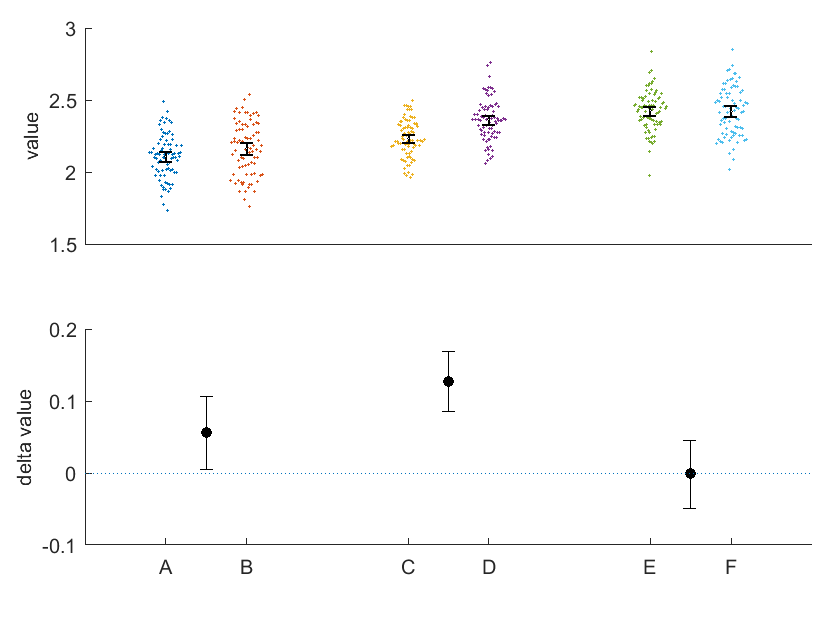

dabest('table1.csv');  


%all data is single vector of LFP for beta 
%Betadatatable (everything, 3*6*82)
%allData = data column = (1,(3*6*82))
%bandIDs = contact 
%groupIDS = runs 
%change varnames to 
%DONT change anything else 
[~,~,stats]  = anovan(datacolumn,{contactcolumn, runcolumn},'model',2,'varnames',{'Contacts','Runs'},'display','off');
[results,~,~,gnames] = multcompare(stats,"Dimension",[1 2],'display','off');

tbl = array2table(results,"VariableNames", ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"]);
tbl.("Group A")=gnames(tbl.("Group A"));
tbl.("Group B")=gnames(tbl.("Group B"));


dir = readtable("PtDirectorySimple.xlsx");
i = 3; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 2 L All Channels


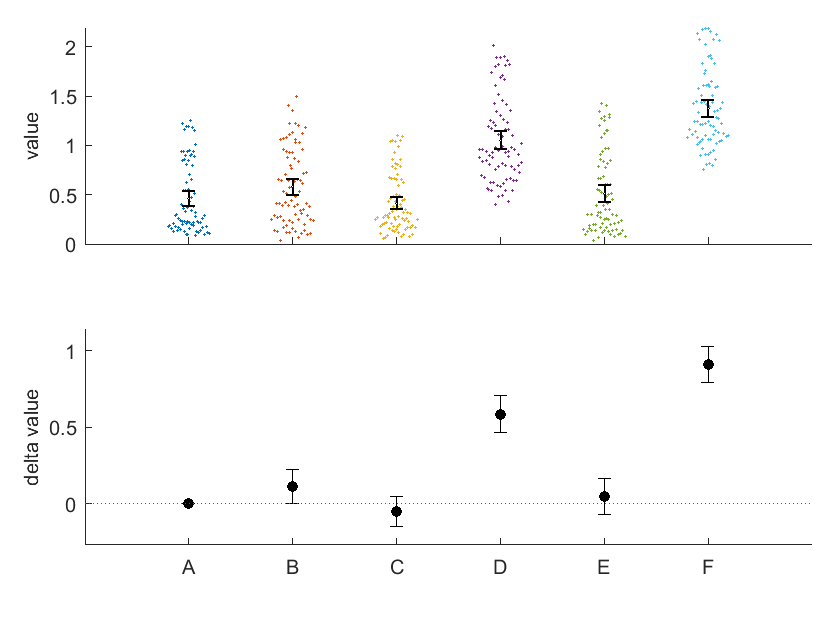

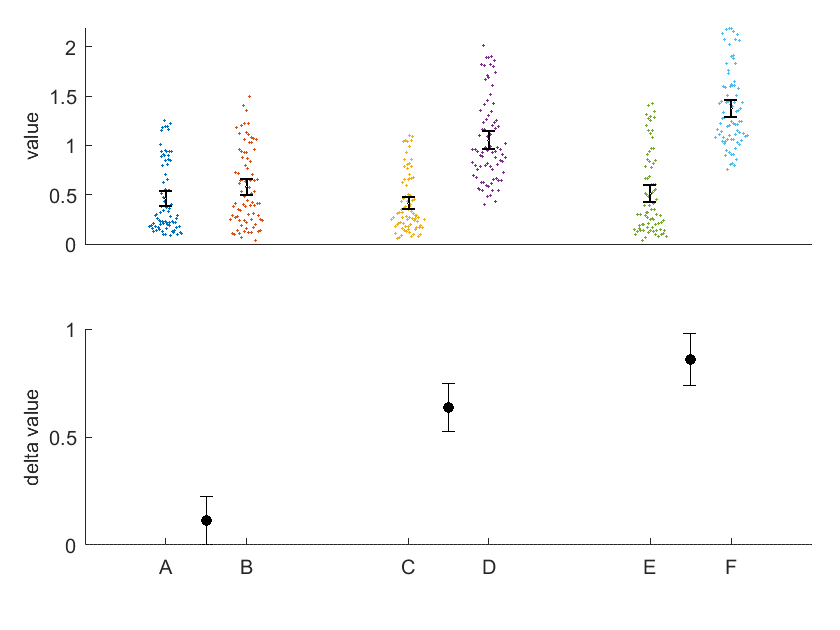

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 4; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 2 R All Channels


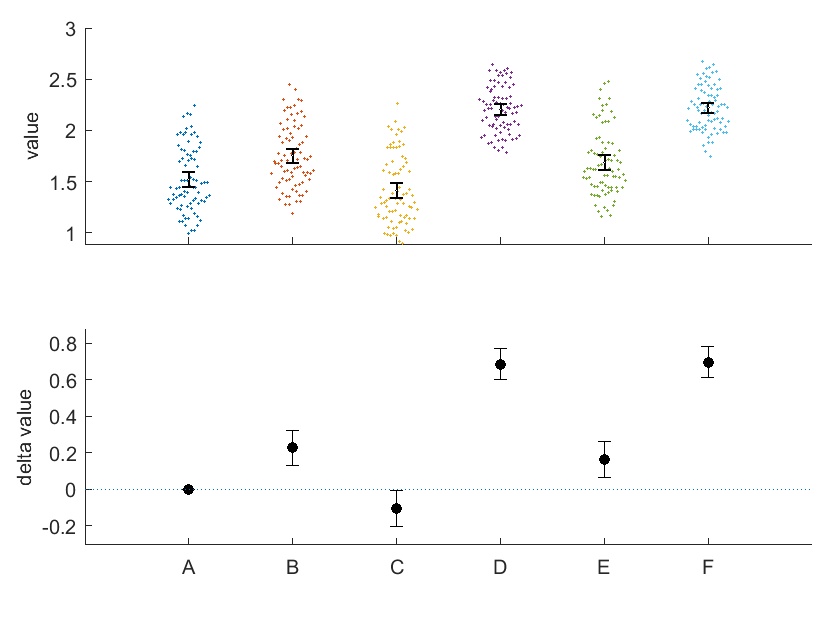

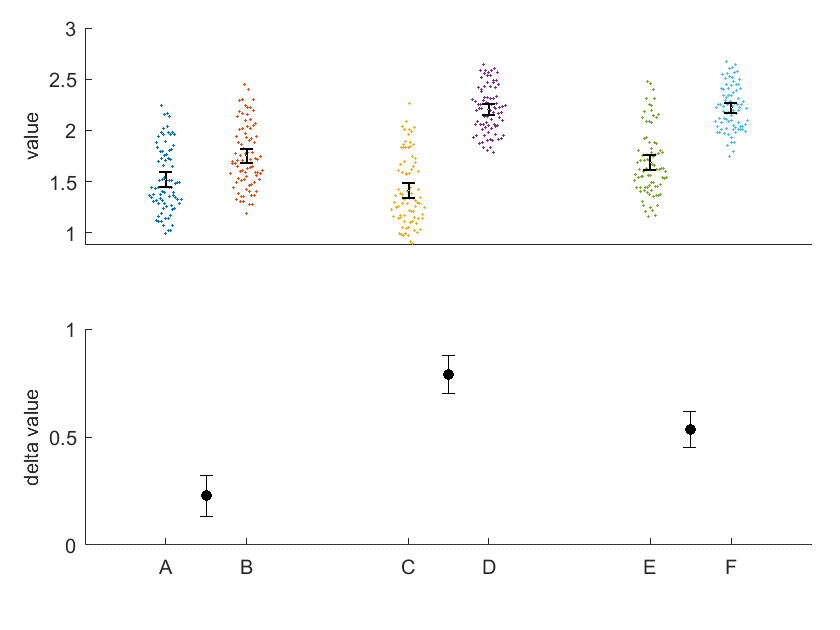

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 5; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 3 L All Channels


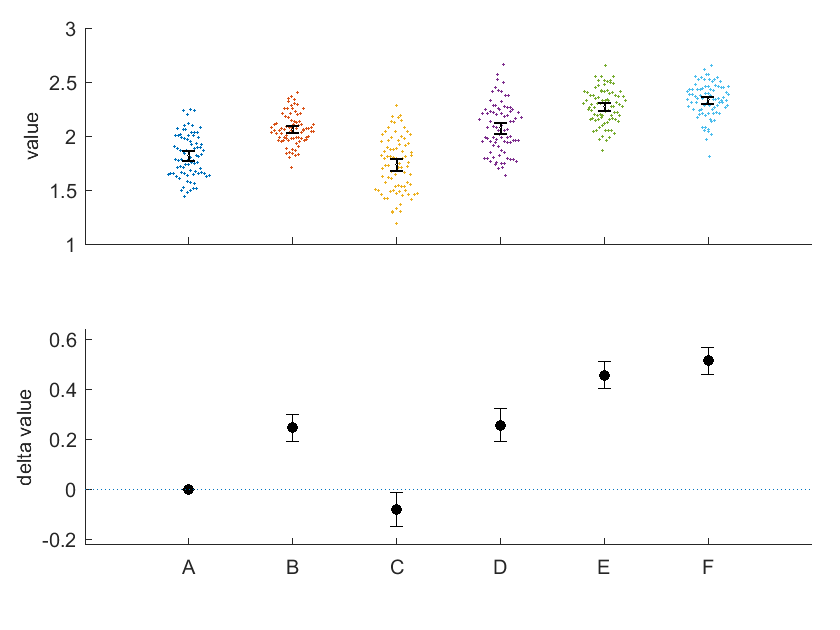

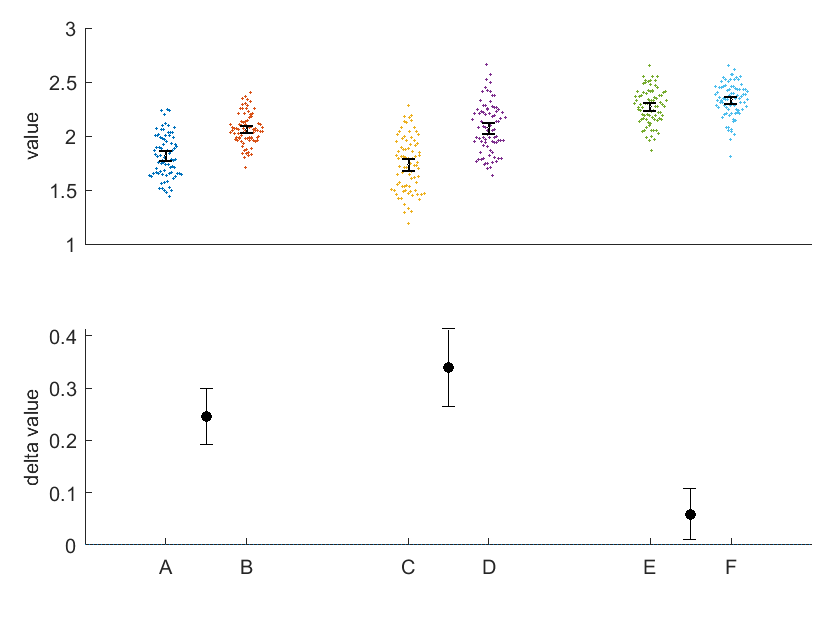

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 6; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 3 R All Channels


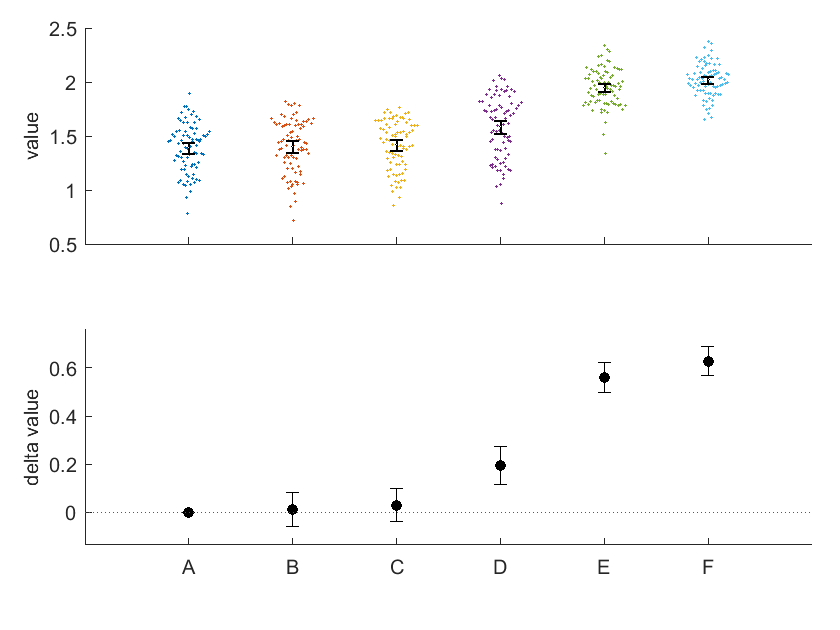

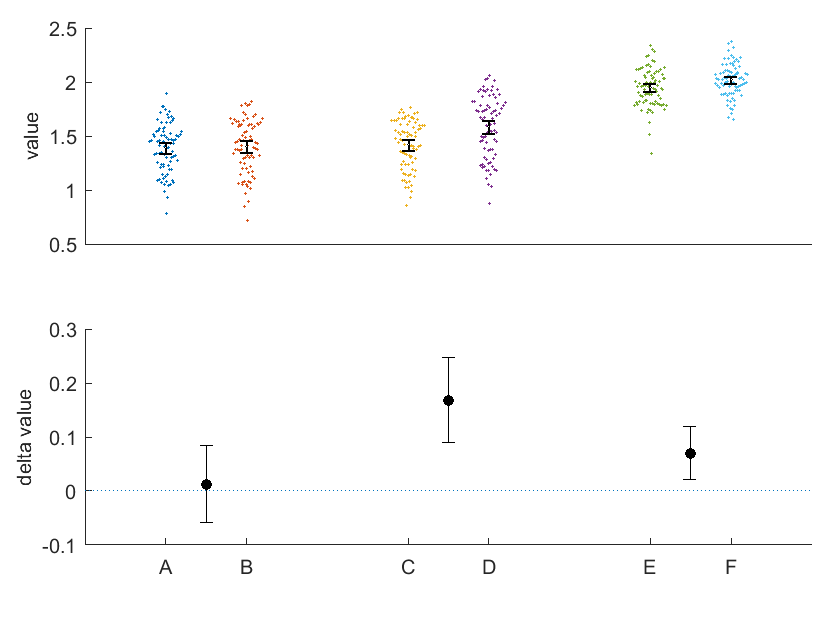

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 7; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 4 R All Channels


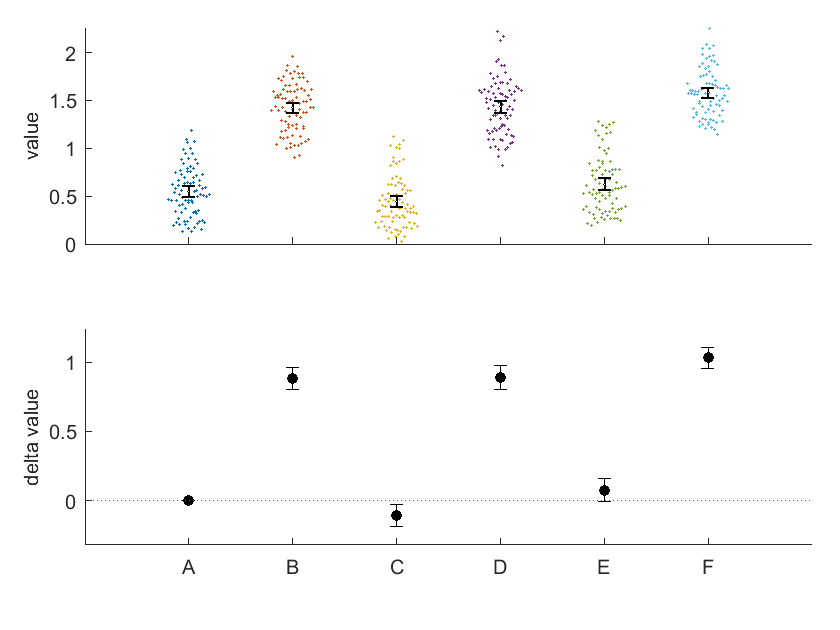

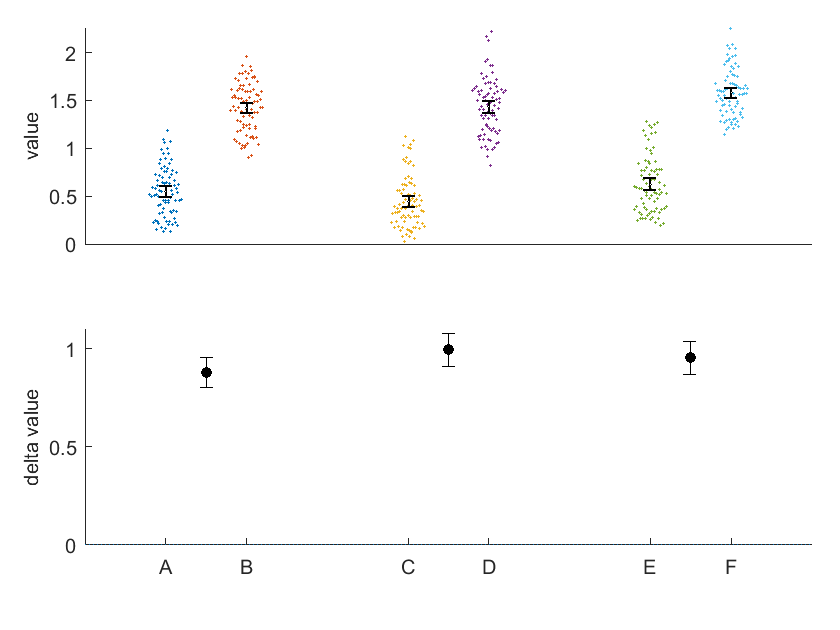

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 8; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 5 L All Channels


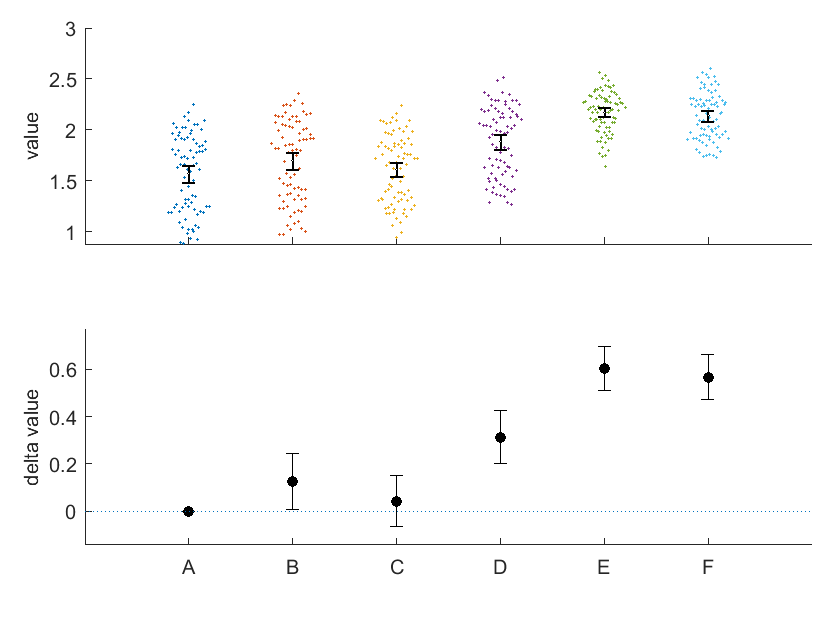

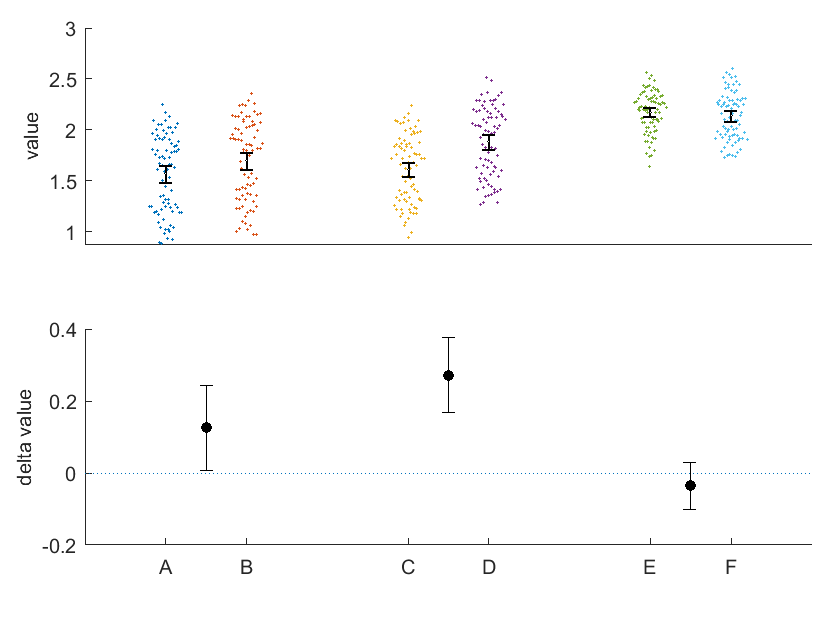

dabest('table1.csv'); 

dir = readtable("PtDirectorySimple.xlsx");
i = 9; 
jsonFiles = dir.JsonSurvey{i};
side = dir.Hemisphere{i};
startIndex = dir.StartIndex(i);
num = num2str(dir.Patient(i));
hemi = upper(dir.Hemisphere(i));
c = split(dir.MaxBeta{i});

js = jsondecode(fileread(jsonFiles));
outTABLE = extractSurveyData(js, side, startIndex);
chans = unique(outTABLE.ChanID, 'stable');

allChan = allChanStats(outTABLE); 
writetable(allChan, 'table1.csv');
disp(append("Pt ", num, " ", hemi, " All Channels"));

Pt 5 R All Channels


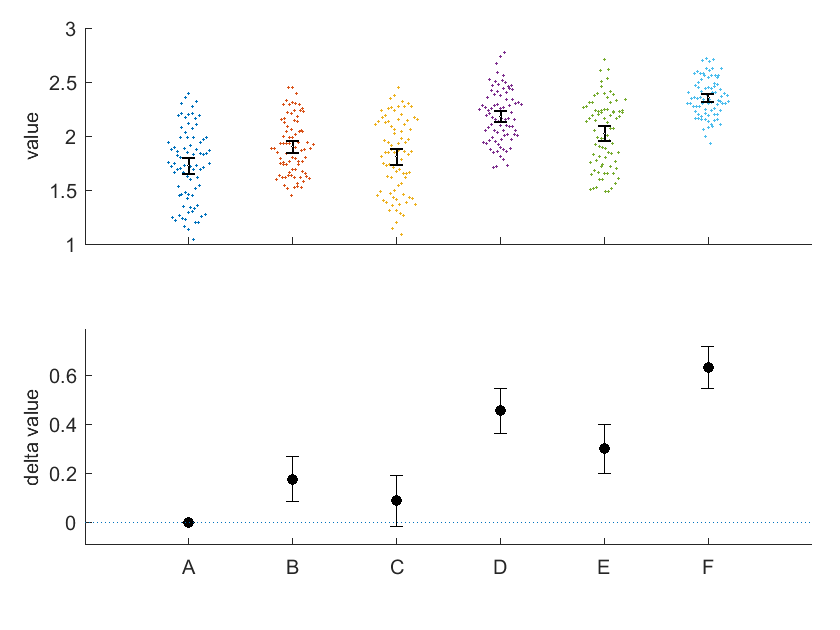

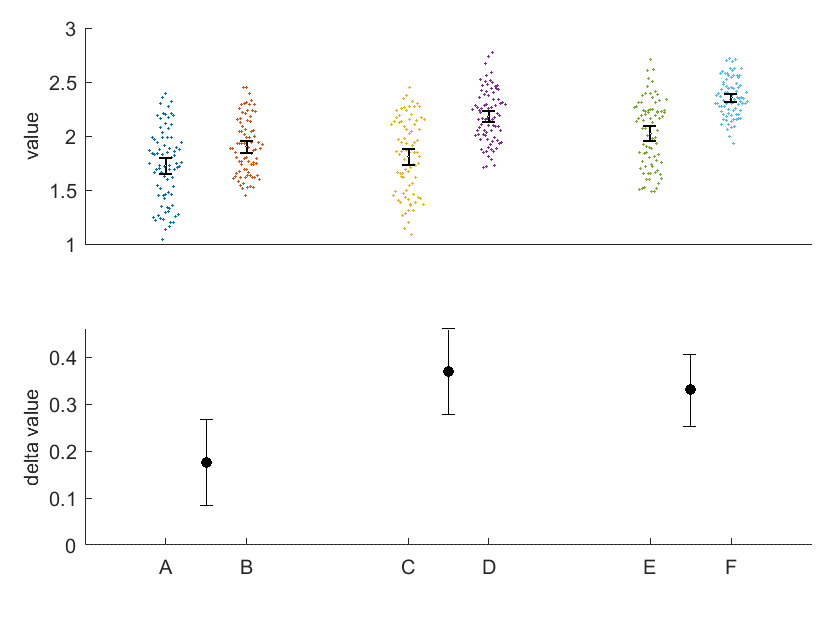

dabest('table1.csv'); 